# Data Transformations

## All histone readers, writers, and erasers (200 genes)

The thought of adding all the histone readers writers, and erasers is that there are relationships with the other histone modifying genes that influence histone acetylation and methylation. This is evaluated by the adjusted $R^2$, which takes into account the size of the dataset.

% Read in CSV file containing all the data
CCLEComp = readtable('CCLECompModelAll.csv', ...
    'ReadVariableNames', true, ...
    'ReadRowNames', true);

cellLines = CCLEComp.Properties.RowNames;
features = CCLEComp.Properties.VariableNames;

% Split into gene expression, histone proteomics, and reaction sets
genes = features(:, 1:201);
geneExpression = CCLEComp(:, 1:201);

histoneMarkers = features(:, 202:243);
histoneProteomics = CCLEComp(:, 202:243);

reactions = features(:, 244:end);
flux = CCLEComp(:, 244:end);

% Top reactions with highest variance
fluxData = table2array(flux);
[sortedVariance, index] = sort(var(fluxData), 'descend');
top400Rxns = reactions(1, index([1:400]));
top400Fluxes = normalize(fluxData(:, index([1:400])), 'zscore');

reactionCorrMatrix = corr(top400Fluxes);
tmp = reactionCorrMatrix - diag(diag(reactionCorrMatrix));
rowsToDelete = any((tmp > 0.9 | tmp < -0.9), 2);
colsToDelete = any((tmp > 0.9 | tmp < -0.9), 1);
tmp(rowsToDelete, :) = [];
tmp(:, colsToDelete) = [];
finalRxnCorrMat = tmp;

finalRxns = top400Rxns;
finalRxns(:, colsToDelete) = [];
BestFluxes = top400Fluxes;
BestFluxes(:, colsToDelete) = [];

% Histone flux reactions only
histoneReactions = reactions(1, [3752, 3759, 3760, 3761]);
histoneFluxes = fluxData(:, [3752, 3759, 3760, 3761]);

% Histone and Histone Metabolism Reactions
fid = fopen('HistoneReactions.txt');
listOfReactions = textscan(fid, '%s', ...
    'delimiter', '\n');
fclose(fid);
listOfReactions = listOfReactions{:};

idx = find(ismember(reactions, listOfReactions));
histMetReactions = reactions(1, idx);
histMetFluxes = fluxData(:, idx);

Okay, next I wanted to try several transformations of both the predictors and the response variables. By seeing how well the model performs in response to the variable transformations, we can start to see what non-linear relationships account for what we're seeing in the models.

### Z-score transformations

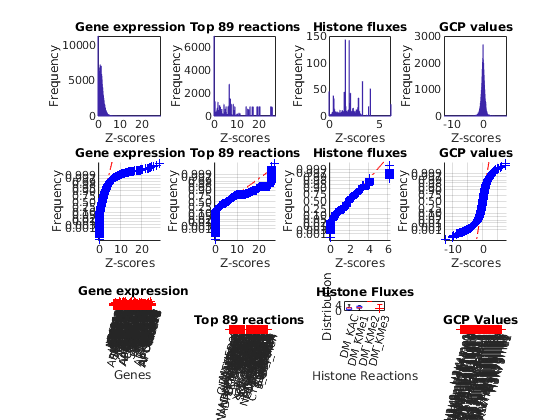

ZObj =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
geneNorm = normalize(geneExpression, 'zscore');
minGeneNorm = min(table2array(geneNorm));
XNormData = table2array(geneNorm);
scaledGenes = zeros(size(XNormData));
for i = 1:size(geneNorm, 2)
    scaledGenes(:, i) = XNormData(:, i) - minGeneNorm(i);
end
scaledGenes(scaledGenes == 0) = NaN;
scaledGenes = array2table(scaledGenes);
scaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Top Reaction Fluxes
fluxNorm = normalize(BestFluxes, 'zscore');
minFluxNorm = min(fluxNorm);
scaledFlux = zeros(size(fluxNorm));
for i = 1:size(fluxNorm, 2)
    scaledFlux(:, i) = fluxNorm(:, i) - minFluxNorm(i);
end
scaledFlux(scaledFlux == 0) = NaN;
scaledFlux = array2table(scaledFlux);
scaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
histFluxNorm = normalize(histoneFluxes, 'zscore');
minFluxNorm = min(histFluxNorm);
scaledHistFlux = zeros(size(histFluxNorm));
for i = 1:size(histFluxNorm, 2)
    scaledHistFlux(:, i) = histFluxNorm(:, i) - minFluxNorm(i);
end
scaledHistFlux(scaledHistFlux == 0) = NaN;
scaledHistFlux = array2table(scaledHistFlux);
scaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone and Metabolism Fluxes
histMetFluxNorm = normalize(histMetFluxes, 'zscore');
minFluxNorm = min(histMetFluxNorm);
scaledHistMetFlux = zeros(size(histMetFluxNorm));
for i = 1:size(histMetFluxNorm, 2)
    scaledHistMetFlux(:, i) = histMetFluxNorm(:, i) - minFluxNorm(i);
end
scaledHistMetFlux(scaledHistMetFlux == 0) = NaN;
scaledHistMetFlux = array2table(scaledHistMetFlux);
scaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Plot Z-score diagnostics
ZObj = exploreExpressionData(scaledGenes, scaledFlux, scaledHistFlux, histoneProteomics)

### Log10 transformations

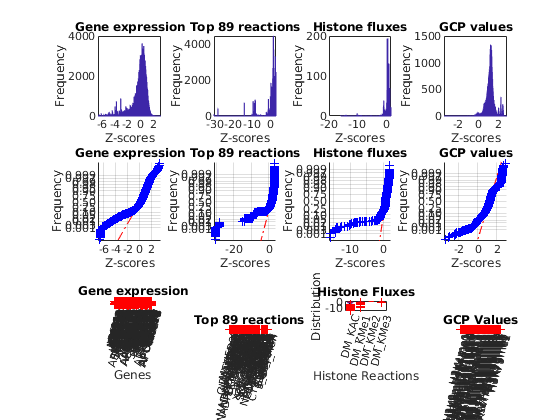

log10Obj =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
XNormData = table2array(scaledGenes);
logScaledGenes = log(XNormData);
logScaledGenes = array2table(logScaledGenes);
logScaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Fluxes
FluxNormData = table2array(scaledFlux);
logScaledFlux = log(FluxNormData);
logScaledFlux = array2table(logScaledFlux);
logScaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
logScaledHistFlux = log(HistFluxNormData);
logScaledHistFlux = array2table(logScaledHistFlux);
logScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Metabolism Reaction Fluxes
HistMetFluxNormData = table2array(scaledHistMetFlux);
logScaledHistMetFlux = log(HistMetFluxNormData);
logScaledHistMetFlux = array2table(logScaledHistMetFlux);
logScaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Proteomics
minProtNorm = min(table2array(histoneProteomics));
YNormData = table2array(histoneProteomics);
logProtNorm = zeros(size(YNormData));
for i = 1:length(minProtNorm)
    logProtNorm(:, i) = YNormData(:, i) - minProtNorm(i);
end
logProtNorm(logProtNorm == 0) = NaN;
logProtNorm = log(logProtNorm);
logProtNorm = array2table(logProtNorm);
logProtNorm.Properties.VariableNames = histoneProteomics.Properties.VariableNames;

% Plot log-scale diagnostics
log10Obj = exploreExpressionData(logScaledGenes, logScaledFlux, logScaledHistFlux, logProtNorm)

### Square root transformations

% Gene Expression
sqrtScaledGenes = sqrt(XNormData);
sqrtScaledGenes(sqrtScaledGenes == 0) = NaN;
sqrtScaledGenes = array2table(sqrtScaledGenes);
sqrtScaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Fluxes
FluxNormData = table2array(scaledFlux);
sqrtScaledFlux = sqrt(FluxNormData);
sqrtScaledFlux = array2table(sqrtScaledFlux);
sqrtScaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
sqrtScaledHistFlux = sqrt(HistFluxNormData);
sqrtScaledHistFlux = array2table(sqrtScaledHistFlux);
sqrtScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Metabolism Reaction Fluxes
HistMetFluxNormData = table2array(scaledHistMetFlux);
sqrtScaledHistMetFlux = log(HistMetFluxNormData);
sqrtScaledHistMetFlux = array2table(sqrtScaledHistMetFlux);
sqrtScaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Proteomics
minProtNorm = min(table2array(histoneProteomics));
YNormData = table2array(histoneProteomics);
sqrtProtNorm = zeros(size(YNormData));
for i = 1:length(minProtNorm)
    sqrtProtNorm(:, i) = YNormData(:, i) - minProtNorm(i);
end
sqrtProtNorm(sqrtProtNorm == 0) = NaN;
sqrtProtNorm = sqrt(sqrtProtNorm);
sqrtProtNorm = array2table(sqrtProtNorm);
sqrtProtNorm.Properties.VariableNames = histoneProteomics.Properties.VariableNames;

% Plot square-root diagnostics
sqrtObj = exploreExpressionData(sqrtGeneNorm, sqrtScaledFlux, sqrtScaledHistFlux, sqrtProtNorm)

From this analysis, I concluded that the best representations of the data for each data type are:

- Gene expression: Z-transformation

- Reaction Flux: Square-root transformation

- Proteomics: Z-transformation

## Histone Methylation and Acetylation Histone Erasers and Writers only

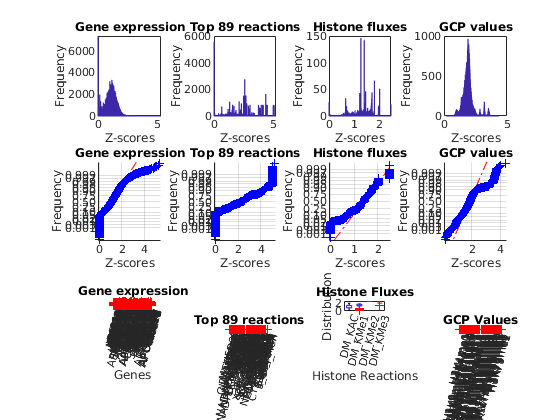

sqrtObj =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


CCLEComp = readtable('CCLECompModelAllMeAc.csv', ...

    'ReadVariableNames', true, ...
    'ReadRowNames', true);
cellLines = CCLEComp.Properties.RowNames;
features = CCLEComp.Properties.VariableNames;

cellLines = CCLEComp.Properties.RowNames;
features = CCLEComp.Properties.VariableNames;


% Split into gene expression, histone proteomics, and reaction sets
genes = features(:, 1:106);
geneExpression = CCLEComp(:, 1:106);

histoneMarkers = features(:, 107:148);
histoneProteomics = CCLEComp(:, 107:148);

reactions = features(:, 149:end);
flux = CCLEComp(:, 149:end);

% Top reactions with highest variance
fluxData = table2array(flux);
[sortedVariance, index] = sort(var(fluxData), 'descend');
top400Rxns = reactions(1, index([1:400]));
top400Fluxes = normalize(fluxData(:, index([1:400])), 'zscore');

reactionCorrMatrix = corr(top400Fluxes);
tmp = reactionCorrMatrix - diag(diag(reactionCorrMatrix));
rowsToDelete = any((tmp > 0.9 | tmp < -0.9), 2);
colsToDelete = any((tmp > 0.9 | tmp < -0.9), 1);
tmp(rowsToDelete, :) = [];
tmp(:, colsToDelete) = [];
finalRxnCorrMat = tmp;

finalRxns = top400Rxns;
finalRxns(:, colsToDelete) = [];
BestFluxes = top400Fluxes;
BestFluxes(:, colsToDelete) = [];

% Histone flux reactions only
histoneReactions = reactions(1, [3752, 3759, 3760, 3761]);
histoneFluxes = fluxData(:, [3752, 3759, 3760, 3761]);

% Histone and Histone Metabolism Reactions
fid = fopen('HistoneReactions.txt');
listOfReactions = textscan(fid, '%s', ...
    'delimiter', '\n');
fclose(fid);
listOfReactions = listOfReactions{:};

idx = find(ismember(reactions, listOfReactions));
histMetReactions = reactions(1, idx);
histMetFluxes = fluxData(:, idx);

### Z-score transformations

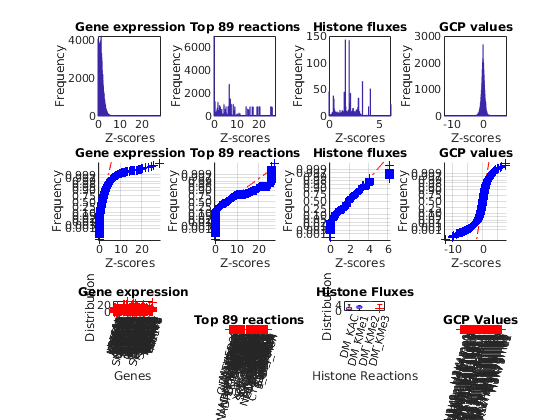

ZObj =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
geneNorm = normalize(geneExpression, 'zscore');
minGeneNorm = min(table2array(geneNorm));
XNormData = table2array(geneNorm);
scaledGenes = zeros(size(XNormData));
for i = 1:size(geneNorm, 2)
    scaledGenes(:, i) = XNormData(:, i) - minGeneNorm(i);
end
scaledGenes(scaledGenes == 0) = NaN;
scaledGenes = array2table(scaledGenes);
scaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Top Reaction Fluxes
fluxNorm = normalize(BestFluxes, 'zscore');
minFluxNorm = min(fluxNorm);
scaledFlux = zeros(size(fluxNorm));
for i = 1:size(fluxNorm, 2)
    scaledFlux(:, i) = fluxNorm(:, i) - minFluxNorm(i);
end
scaledFlux(scaledFlux == 0) = NaN;
scaledFlux = array2table(scaledFlux);
scaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
histFluxNorm = normalize(histoneFluxes, 'zscore');
minFluxNorm = min(histFluxNorm);
scaledHistFlux = zeros(size(histFluxNorm));
for i = 1:size(histFluxNorm, 2)
    scaledHistFlux(:, i) = histFluxNorm(:, i) - minFluxNorm(i);
end
scaledHistFlux(scaledHistFlux == 0) = NaN;
scaledHistFlux = array2table(scaledHistFlux);
scaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone and Metabolism Fluxes
histMetFluxNorm = normalize(histMetFluxes, 'zscore');
minFluxNorm = min(histMetFluxNorm);
scaledHistMetFlux = zeros(size(histMetFluxNorm));
for i = 1:size(histMetFluxNorm, 2)
    scaledHistMetFlux(:, i) = histMetFluxNorm(:, i) - minFluxNorm(i);
end
scaledHistMetFlux(scaledHistMetFlux == 0) = NaN;
scaledHistMetFlux = array2table(scaledHistMetFlux);
scaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Plot Z-score diagnostics
ZObj = exploreExpressionData(scaledGenes, scaledFlux, scaledHistFlux, histoneProteomics)

### Log10 transformations

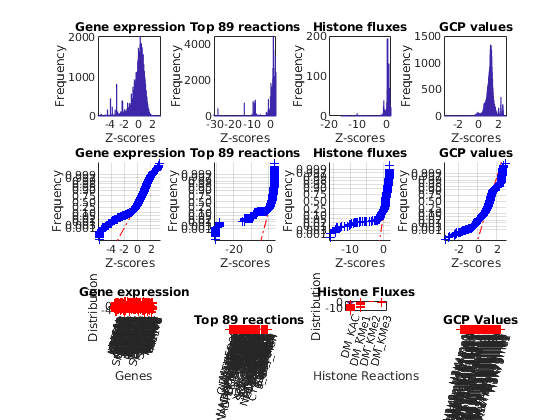

log10Obj =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


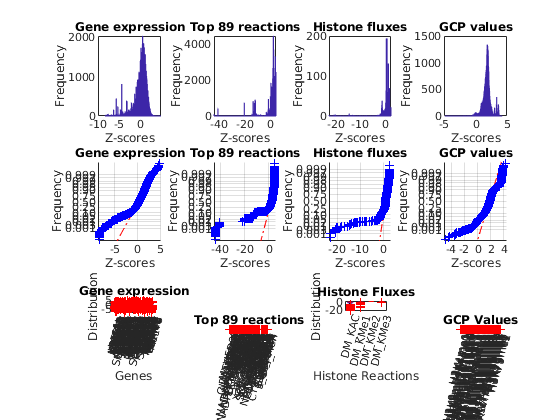

log2Obj =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


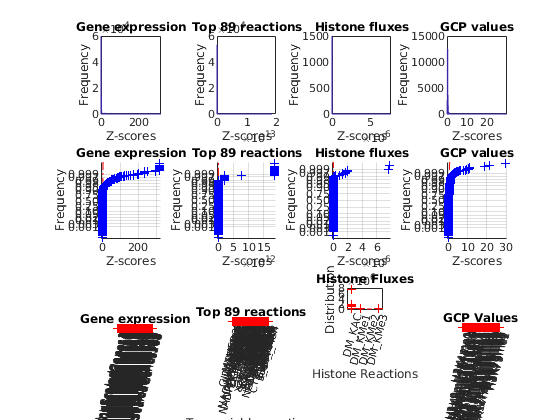

invObj =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
XNormData = table2array(scaledGenes);
logScaledGenes = log(XNormData);
logScaledGenes = array2table(logScaledGenes);
logScaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Fluxes
FluxNormData = table2array(scaledFlux);
logScaledFlux = log(FluxNormData);
logScaledFlux = array2table(logScaledFlux);
logScaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
logScaledHistFlux = log(HistFluxNormData);
logScaledHistFlux = array2table(logScaledHistFlux);
logScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Metabolism Reaction Fluxes
HistMetFluxNormData = table2array(scaledHistMetFlux);
logScaledHistMetFlux = log(HistMetFluxNormData);
logScaledHistMetFlux = array2table(logScaledHistMetFlux);
logScaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Proteomics
minProtNorm = min(table2array(histoneProteomics));
YNormData = table2array(histoneProteomics);
logProtNorm = zeros(size(YNormData));
for i = 1:length(minProtNorm)
    logProtNorm(:, i) = YNormData(:, i) - minProtNorm(i);
end
logProtNorm(logProtNorm == 0) = NaN;
logProtNorm = log(logProtNorm);
logProtNorm = array2table(logProtNorm);
logProtNorm.Properties.VariableNames = histoneProteomics.Properties.VariableNames;

% Plot log-scale diagnostics
log10Obj = exploreExpressionData(logScaledGenes, logScaledFlux, logScaledHistFlux, logProtNorm)

### Square root transformations

sqrtObj =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
sqrtScaledGenes = sqrt(XNormData);
sqrtScaledGenes(sqrtScaledGenes == 0) = NaN;
sqrtScaledGenes = array2table(sqrtScaledGenes);
sqrtScaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Fluxes
FluxNormData = table2array(scaledFlux);
sqrtScaledFlux = sqrt(FluxNormData);
sqrtScaledFlux = array2table(sqrtScaledFlux);
sqrtScaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
sqrtScaledHistFlux = sqrt(HistFluxNormData);
sqrtScaledHistFlux = array2table(sqrtScaledHistFlux);
sqrtScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Metabolism Reaction Fluxes
HistMetFluxNormData = table2array(scaledHistMetFlux);
sqrtScaledHistMetFlux = log(HistMetFluxNormData);
sqrtScaledHistMetFlux = array2table(sqrtScaledHistMetFlux);
sqrtScaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Proteomics
minProtNorm = min(table2array(histoneProteomics));
YNormData = table2array(histoneProteomics);
sqrtProtNorm = zeros(size(YNormData));
for i = 1:length(minProtNorm)
    sqrtProtNorm(:, i) = YNormData(:, i) - minProtNorm(i);
end
sqrtProtNorm(sqrtProtNorm == 0) = NaN;
sqrtProtNorm = sqrt(sqrtProtNorm);
sqrtProtNorm = array2table(sqrtProtNorm);
sqrtProtNorm.Properties.VariableNames = histoneProteomics.Properties.VariableNames;

% Plot square-root diagnostics
sqrtObj = exploreExpressionData(sqrtGeneNorm, sqrtScaledFlux, sqrtScaledHistFlux, sqrtProtNorm)

## Histone Methylation and Acetylation Writers only

CCLEComp = readtable('CCLECompModelMeAcWriters.csv', ...
    'ReadVariableNames', true, ...
    'ReadRowNames', true);
cellLines = CCLEComp.Properties.RowNames;

features = CCLEComp.Properties.VariableNames;

cellLines = CCLEComp.Properties.RowNames;
features = CCLEComp.Properties.VariableNames;

% Split into gene expression, histone proteomics, and reaction sets
genes = features(:, 1:69);
geneExpression = CCLEComp(:, 1:69);

histoneMarkers = features(:, 70:111);
histoneProteomics = CCLEComp(:, 70:111);

reactions = features(:, 112:end);
flux = CCLEComp(:, 112:end);

% Top reactions with highest variance
fluxData = table2array(flux);
[sortedVariance, index] = sort(var(fluxData), 'descend');
top400Rxns = reactions(1, index([1:400]));
top400Fluxes = normalize(fluxData(:, index([1:400])), 'zscore');

reactionCorrMatrix = corr(top400Fluxes);
tmp = reactionCorrMatrix - diag(diag(reactionCorrMatrix));
rowsToDelete = any((tmp > 0.9 | tmp < -0.9), 2);
colsToDelete = any((tmp > 0.9 | tmp < -0.9), 1);
tmp(rowsToDelete, :) = [];
tmp(:, colsToDelete) = [];
finalRxnCorrMat = tmp;

finalRxns = top400Rxns;
finalRxns(:, colsToDelete) = [];
BestFluxes = top400Fluxes;
BestFluxes(:, colsToDelete) = [];

% Histone flux reactions only
histoneReactions = reactions(1, [3752, 3759, 3760, 3761]);
histoneFluxes = fluxData(:, [3752, 3759, 3760, 3761]);

% Histone and Histone Metabolism Reactions
fid = fopen('HistoneReactions.txt');
listOfReactions = textscan(fid, '%s', ...
    'delimiter', '\n');
fclose(fid);
listOfReactions = listOfReactions{:};

idx = find(ismember(reactions, listOfReactions));
histMetReactions = reactions(1, idx);
histMetFluxes = fluxData(:, idx);

### Z-score transformations

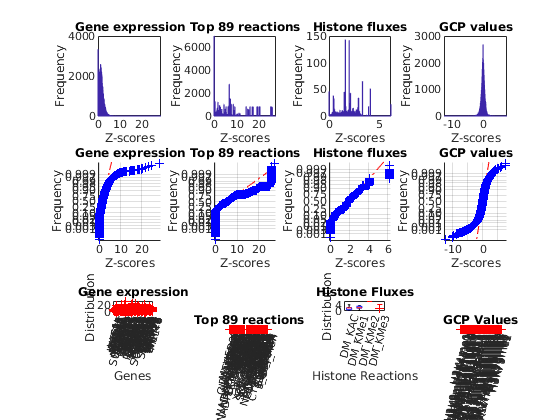

ZObj =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
geneNorm = normalize(geneExpression, 'zscore');
minGeneNorm = min(table2array(geneNorm));
XNormData = table2array(geneNorm);
scaledGenes = zeros(size(XNormData));
for i = 1:size(geneNorm, 2)
    scaledGenes(:, i) = XNormData(:, i) - minGeneNorm(i);
end
scaledGenes(scaledGenes == 0) = NaN;
scaledGenes = array2table(scaledGenes);
scaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Top Reaction Fluxes
fluxNorm = normalize(BestFluxes, 'zscore');
minFluxNorm = min(fluxNorm);
scaledFlux = zeros(size(fluxNorm));
for i = 1:size(fluxNorm, 2)
    scaledFlux(:, i) = fluxNorm(:, i) - minFluxNorm(i);
end
scaledFlux(scaledFlux == 0) = NaN;
scaledFlux = array2table(scaledFlux);
scaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
histFluxNorm = normalize(histoneFluxes, 'zscore');
minFluxNorm = min(histFluxNorm);
scaledHistFlux = zeros(size(histFluxNorm));
for i = 1:size(histFluxNorm, 2)
    scaledHistFlux(:, i) = histFluxNorm(:, i) - minFluxNorm(i);
end
scaledHistFlux(scaledHistFlux == 0) = NaN;
scaledHistFlux = array2table(scaledHistFlux);
scaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone and Metabolism Fluxes
histMetFluxNorm = normalize(histMetFluxes, 'zscore');
minFluxNorm = min(histMetFluxNorm);
scaledHistMetFlux = zeros(size(histMetFluxNorm));
for i = 1:size(histMetFluxNorm, 2)
    scaledHistMetFlux(:, i) = histMetFluxNorm(:, i) - minFluxNorm(i);
end
scaledHistMetFlux(scaledHistMetFlux == 0) = NaN;
scaledHistMetFlux = array2table(scaledHistMetFlux);
scaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Plot Z-score diagnostics
ZObj = exploreExpressionData(scaledGenes, scaledFlux, scaledHistFlux, histoneProteomics)

### Log10 transformations

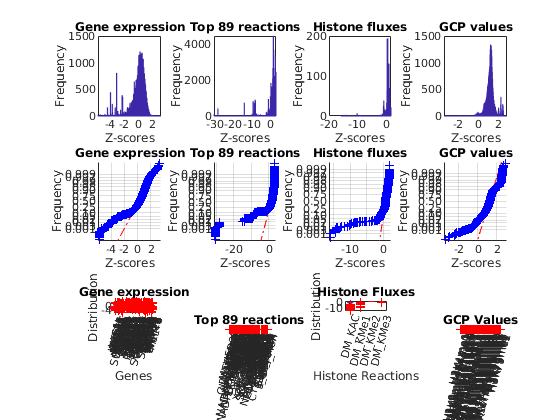

log10Obj =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
XNormData = table2array(scaledGenes);
logScaledGenes = log(XNormData);
logScaledGenes = array2table(logScaledGenes);
logScaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Fluxes
FluxNormData = table2array(scaledFlux);
logScaledFlux = log(FluxNormData);
logScaledFlux = array2table(logScaledFlux);
logScaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
logScaledHistFlux = log(HistFluxNormData);
logScaledHistFlux = array2table(logScaledHistFlux);
logScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Metabolism Reaction Fluxes
HistMetFluxNormData = table2array(scaledHistMetFlux);
logScaledHistMetFlux = log(HistMetFluxNormData);
logScaledHistMetFlux = array2table(logScaledHistMetFlux);
logScaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Proteomics
minProtNorm = min(table2array(histoneProteomics));
YNormData = table2array(histoneProteomics);
logProtNorm = zeros(size(YNormData));
for i = 1:length(minProtNorm)
    logProtNorm(:, i) = YNormData(:, i) - minProtNorm(i);
end
logProtNorm(logProtNorm == 0) = NaN;
logProtNorm = log(logProtNorm);
logProtNorm = array2table(logProtNorm);
logProtNorm.Properties.VariableNames = histoneProteomics.Properties.VariableNames;

% Plot log-scale diagnostics
log10Obj = exploreExpressionData(logScaledGenes, logScaledFlux, logScaledHistFlux, logProtNorm)

### Square root transformations

% Gene Expression
sqrtScaledGenes = sqrt(XNormData);
sqrtScaledGenes(sqrtScaledGenes == 0) = NaN;
sqrtScaledGenes = array2table(sqrtScaledGenes);
sqrtScaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Fluxes
FluxNormData = table2array(scaledFlux);
sqrtScaledFlux = sqrt(FluxNormData);
sqrtScaledFlux = array2table(sqrtScaledFlux);
sqrtScaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
sqrtScaledHistFlux = sqrt(HistFluxNormData);
sqrtScaledHistFlux = array2table(sqrtScaledHistFlux);
sqrtScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
sqrtScaledHistFlux = sqrt(HistFluxNormData);
sqrtScaledHistFlux = array2table(sqrtScaledHistFlux);
sqrtScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Metabolism Reaction Fluxes
HistMetFluxNormData = table2array(scaledHistMetFlux);
sqrtScaledHistMetFlux = log(HistMetFluxNormData);
sqrtScaledHistMetFlux = array2table(sqrtScaledHistMetFlux);
sqrtScaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Proteomics
minProtNorm = min(table2array(histoneProteomics));
YNormData = table2array(histoneProteomics);
sqrtProtNorm = zeros(size(YNormData));
for i = 1:length(minProtNorm)
    sqrtProtNorm(:, i) = YNormData(:, i) - minProtNorm(i);
end
sqrtProtNorm(sqrtProtNorm == 0) = NaN;
sqrtProtNorm = sqrt(sqrtProtNorm);
sqrtProtNorm = array2table(sqrtProtNorm);
sqrtProtNorm.Properties.VariableNames = histoneProteomics.Properties.VariableNames;

% Plot square-root diagnostics
sqrtObj = exploreExpressionData(sqrtGeneNorm, sqrtScaledFlux, sqrtScaledHistFlux, sqrtProtNorm)

## Histone Methylation and Acetylation Erasers only

sqrtObj =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


CCLEComp = readtable('CCLECompModelMeAcErasers.csv', ...

    'ReadVariableNames', true, ...
    'ReadRowNames', true);
cellLines = CCLEComp.Properties.RowNames;
features = CCLEComp.Properties.VariableNames;


cellLines = CCLEComp.Properties.RowNames;
features = CCLEComp.Properties.VariableNames;

% Split into gene expression, histone proteomics, and reaction sets
genes = features(:, 1:39);
geneExpression = CCLEComp(:, 1:39);

histoneMarkers = features(:, 40:81);
histoneProteomics = CCLEComp(:, 40:81);

reactions = features(:, 82:end);
flux = CCLEComp(:, 82:end);

% Top reactions with highest variance
fluxData = table2array(flux);
[sortedVariance, index] = sort(var(fluxData), 'descend');
top400Rxns = reactions(1, index([1:400]));
top400Fluxes = normalize(fluxData(:, index([1:400])), 'zscore');

reactionCorrMatrix = corr(top400Fluxes);
tmp = reactionCorrMatrix - diag(diag(reactionCorrMatrix));
rowsToDelete = any((tmp > 0.9 | tmp < -0.9), 2);
colsToDelete = any((tmp > 0.9 | tmp < -0.9), 1);
tmp(rowsToDelete, :) = [];
tmp(:, colsToDelete) = [];
finalRxnCorrMat = tmp;

finalRxns = top400Rxns;
finalRxns(:, colsToDelete) = [];
BestFluxes = top400Fluxes;
BestFluxes(:, colsToDelete) = [];

% Histone flux reactions only
histoneReactions = reactions(1, [3752, 3759, 3760, 3761]);
histoneFluxes = fluxData(:, [3752, 3759, 3760, 3761]);

### Z-score transformations

% Gene Expression
geneNorm = normalize(geneExpression, 'zscore');
minGeneNorm = min(table2array(geneNorm));
XNormData = table2array(geneNorm);
scaledGenes = zeros(size(XNormData));
for i = 1:size(geneNorm, 2)
    scaledGenes(:, i) = XNormData(:, i) - minGeneNorm(i);
end
scaledGenes(scaledGenes == 0) = NaN;
scaledGenes = array2table(scaledGenes);
scaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Top Reaction Fluxes
fluxNorm = normalize(BestFluxes, 'zscore');
minFluxNorm = min(fluxNorm);
scaledFlux = zeros(size(fluxNorm));
for i = 1:size(fluxNorm, 2)
    scaledFlux(:, i) = fluxNorm(:, i) - minFluxNorm(i);
end
scaledFlux(scaledFlux == 0) = NaN;
scaledFlux = array2table(scaledFlux);
scaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
histFluxNorm = normalize(histoneFluxes, 'zscore');
minFluxNorm = min(histFluxNorm);
scaledHistFlux = zeros(size(histFluxNorm));
for i = 1:size(histFluxNorm, 2)
    scaledHistFlux(:, i) = histFluxNorm(:, i) - minFluxNorm(i);
end
scaledHistFlux(scaledHistFlux == 0) = NaN;
scaledHistFlux = array2table(scaledHistFlux);
scaledHistFlux.Properties.VariableNames = histoneReactions;

% Plot Z-score diagnostics
ZObj = exploreExpressionData(scaledGenes, scaledFlux, scaledHistFlux, histoneProteomics)

### Log10 transformations

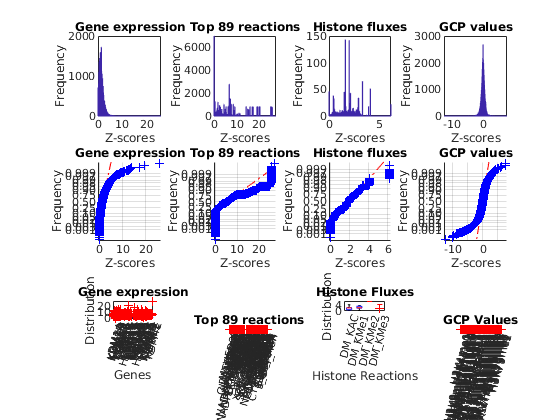

ZObj =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
XNormData = table2array(scaledGenes);

logScaledGenes = log(XNormData);
logScaledGenes = array2table(logScaledGenes);
logScaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Fluxes
FluxNormData = table2array(scaledFlux);
logScaledFlux = log(FluxNormData);
logScaledFlux = array2table(logScaledFlux);
logScaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
logScaledHistFlux = log(HistFluxNormData);
logScaledHistFlux = array2table(logScaledHistFlux);
logScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Metabolism Reaction Fluxes
HistMetFluxNormData = table2array(scaledHistMetFlux);
logScaledHistMetFlux = log(HistMetFluxNormData);
logScaledHistMetFlux = array2table(logScaledHistMetFlux);
logScaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Proteomics
minProtNorm = min(table2array(histoneProteomics));
YNormData = table2array(histoneProteomics);
logProtNorm = zeros(size(YNormData));
for i = 1:length(minProtNorm)
    logProtNorm(:, i) = YNormData(:, i) - minProtNorm(i);
end
logProtNorm(logProtNorm == 0) = NaN;
logProtNorm = log(logProtNorm);
logProtNorm = array2table(logProtNorm);
logProtNorm.Properties.VariableNames = histoneProteomics.Properties.VariableNames;

% Plot log-scale diagnostics
log10Obj = exploreExpressionData(logScaledGenes, logScaledFlux, logScaledHistFlux, logProtNorm)

### Square root transformations

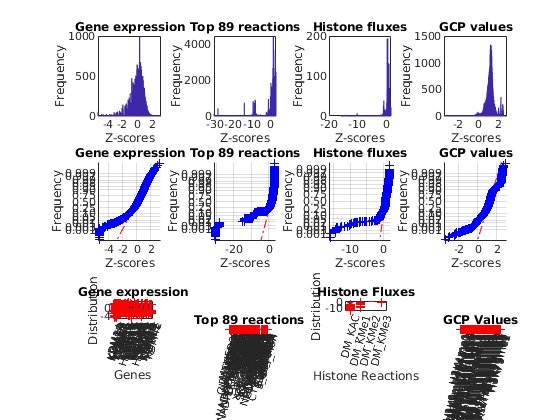

log10Obj =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


% Gene Expression
sqrtScaledGenes = sqrt(XNormData);

sqrtObj =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


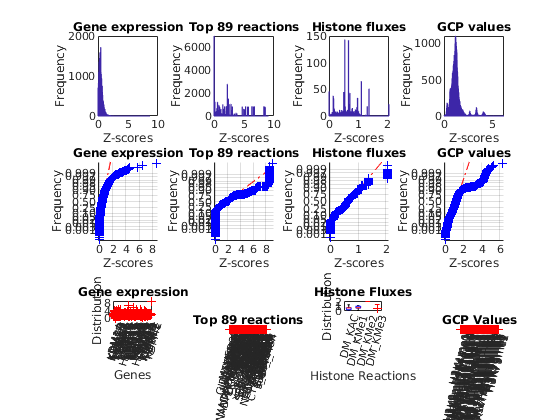

cubeObj =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


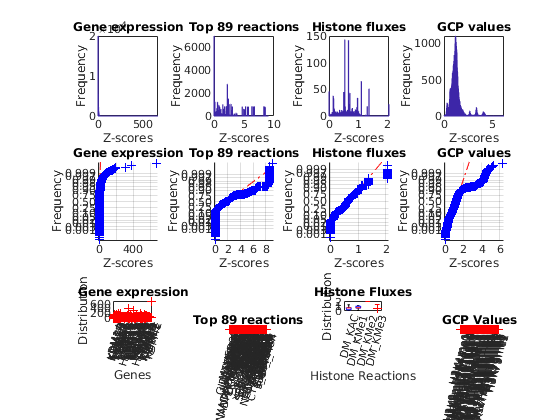

squareObj =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


sqrtScaledGenes(sqrtScaledGenes == 0) = NaN;
sqrtScaledGenes = array2table(sqrtScaledGenes);
sqrtScaledGenes.Properties.VariableNames = geneExpression.Properties.VariableNames;

% Fluxes
FluxNormData = table2array(scaledFlux);
sqrtScaledFlux = sqrt(FluxNormData);
sqrtScaledFlux = array2table(sqrtScaledFlux);
sqrtScaledFlux.Properties.VariableNames = finalRxns;

% Histone Reaction Fluxes
HistFluxNormData = table2array(scaledHistFlux);
sqrtScaledHistFlux = sqrt(HistFluxNormData);
sqrtScaledHistFlux = array2table(sqrtScaledHistFlux);
sqrtScaledHistFlux.Properties.VariableNames = histoneReactions;

% Histone Metabolism Reaction Fluxes
HistMetFluxNormData = table2array(scaledHistMetFlux);
sqrtScaledHistMetFlux = log(HistMetFluxNormData);
sqrtScaledHistMetFlux = array2table(sqrtScaledHistMetFlux);
sqrtScaledHistMetFlux.Properties.VariableNames = histMetReactions;

% Proteomics
minProtNorm = min(table2array(histoneProteomics));
YNormData = table2array(histoneProteomics);
sqrtProtNorm = zeros(size(YNormData));
for i = 1:length(minProtNorm)
    sqrtProtNorm(:, i) = YNormData(:, i) - minProtNorm(i);
end
sqrtProtNorm(sqrtProtNorm == 0) = NaN;
sqrtProtNorm = sqrt(sqrtProtNorm);
sqrtProtNorm = array2table(sqrtProtNorm);
sqrtProtNorm.Properties.VariableNames = histoneProteomics.Properties.VariableNames;

% Plot square-root diagnostics
sqrtObj = exploreExpressionData(sqrtGeneNorm, sqrtScaledFlux, sqrtScaledHistFlux, sqrtProtNorm)